M = 2^12;
N = 2^10;
singular = exp(-(3*(1/N:1/N:1)).^2);
S = diag(singular);
[U, ~] = qr(randn(M, N), "econ");
[V, ~] = qr(randn(N, N), "econ");
A = U * S * V';


tic
f = @RandRangeFinder;
[U1, S1, V1] = RandomSVD(f, A, 50, [1, N]);
toc

历时 0.315032 秒。



tic
f = @IterativeRangeFinder;
[U2, S2, V2] = RandomSVD(f, A, 2, 10);
toc

历时 0.491534 秒。



tic
[U, S, V] = svd(A);
toc

历时 0.478348 秒。


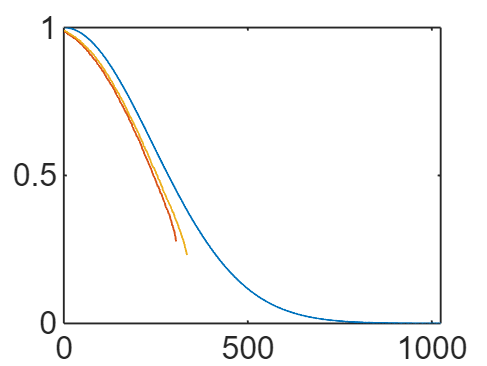

plot(diag(S))
hold on 
plot(diag(S1))
plot(diag(S2))

% low-rank approximation by projection
tic
Q = RandRangeFinder(A, 50, [1, N]);
toc

历时 0.293797 秒。


A_ = Q*(Q'*A);
sum((A_-A).^2, 'all')/sum(A.^2, 'all')

ans = 0.2101

% low-rank approximation by interpolation
tic
[C, X] = RandID(A, ceil(N/4), 10);
toc

历时 0.385942 秒。


A_ = C * X;
sum((A_-A).^2, 'all')/sum(A.^2, 'all')

ans = 0.2808